## Fundação Getúlio Vargas

## Escola de Pós-Graduação em Economia

## Teoria Macroeconômica III

Professor: Ricardo de Oliveira Cavalcanti

Monitora: Kátia Aiko Nishiyama Alves

# Lista 1

**Exercício 01**

Temos um modelo de search no mercado de trabalho com as seguintes funções/parâmetros:

f = @(w, alpha_1, alpha_2) alpha_1 + alpha_2 * w;
u = @(c, gamma) c .^ gamma;

beta = 0.98;
pi = 0.1;
b = 0;
wmin = 0;
wmax = 20;
gamma = 1/2;

**Item (i)**

No item (i) vamos usar que $f(0) = 2f(\overline{w})$. Como $\int_{0}^{\overline{w}} f(w) dw = 1$, resolvemos para $\alpha_1, \alpha_2$ e obtemos:

alpha_1 = 1/15;
alpha_2 = -1/600;

Neste modelo o agente escolhe entre aceitar uma oferta de trabalho a um salário $w$ ou continuar procurando por uma oferta no próximo período a um salário $w'$. Escrevemos o problema do agente na forma recursiva, e resolvemos para obter a função valor $V(w)$, a função política $G(w)$ e o preço de reserva $R$ do agente (o salário que o torna indiferente entre aceitar ou não uma oferta de trabalho).

Para aproximar numericamente a função valor, criamos um grid para a variável de estado $w$, entre 0 e 20, contendo $n = 1000$ pontos, e aplicamos aplicamos um algoritmo de iteração buscando o ponto fixo do operador 


$$T(V)(w) = \underset{I(w) \in \{0,1\}}{max} I(w) \{u(w) + \beta [(1-\pi) V(w) + \pi V(0)] \} + [1-I(w)] [u(b) + \beta E[V(w')]].$$


n = 1000;
w = linspace(wmin, wmax, n)';
V = ones(n, 1); % chute inicial para a função valor
G = ones(n, 1); % chute inicial para a função política

% inicia variaveis do algoritmo de iteracao
err = 1;
tol = 10^-5;
itmax = 2000;
iter = 1;

% fdp discretizada e funcao valor esperado
fw = f(w, alpha_1, alpha_2) ./ sum(f(w, alpha_1, alpha_2));
E = @(fw, V, n) V' * fw; 

Definimos $N$ como o payoff de recusar uma oferta $w$ e seguir a política ótima a partir do próximo período, e $A$ como o payoff de aceitar $w$ e seguir a política ótima a partir do próximo período. Deste modo o algoritmo de iteração 

% algoritmo de iteracao
while err > tol && iter < itmax
    N = u(b, gamma) + beta * E(fw, V, n);
    N = repmat(N, n, 1);
    A = u(w, gamma) + beta * ((1-pi) * V + pi * N);
    [TV, G] = max([N A], [], 2);
    err = abs(max(TV - V));
    V = TV;
    iter = iter + 1;
end

G = G-1;
R = min(w(G == 1));

Resultados:

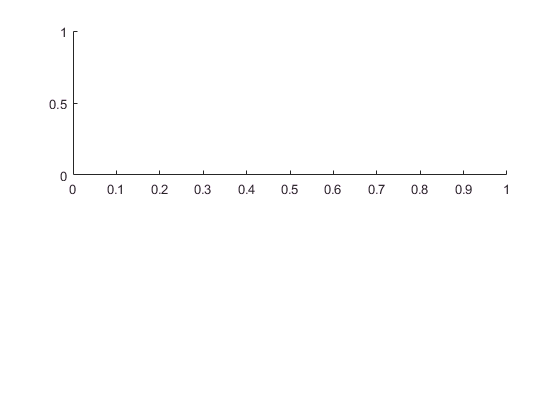

subplot(2,1,1);

plot(w, V);

Undefined function or variable 'x'.

title('Funcao valor');
ylabel('v(w)');
xlabel('w');

subplot(2,1,2);
plot(w, G);
title('Funcao politica');
ylabel('g(w)');
xlabel('w');

R